% Data 
inverter_matrix = [2 -1 -1;
                   -1 2 -1;
                   -1 -1 2];
f = 50;
L = 1.5e-3;
C = 1000e-6;
R = 10;

Vr = 220;
Vc = 700;
V = Vr;


% Te = 1e-7;
% Fs = 1/Te;
% Tf = 0.25;
% len = Tf/Te;
% t = (0:len-1)*Te;
% Vc = 700;
% theta = linspace(0,pi);%2*pi*f*t;
% Fd = 10e3;
% w = 2*pi*f;
% Vrd = abs(Vr*sin(theta));
% m = Im*2*pi*50*cos(theta);
% 
% H_ = ((Vrd-m*L).*(Vc - Vrd + m*L))./(2*Fd*L*Vc);
% plot(theta, H_); grid on;
% title("H=f(\theta)");
% ylabel("H");
% xlabel("\theta")

Im = ((Vc^2)*sqrt(2))/(3*R*Vr)

Im = 104.9946


% % delta = 0 et H != 0
Fd = 10e3;
Td=1/Fd;
H = Vc/(6*L*Fd);

delta = 0;
eps_on =  H;
eps_off = -H;
S_on = 1;
S_off = 0;



wd = 2*pi*Fd;
wbp = wd/sqrt(10);

K = L*wbp;
Ti = sqrt(10)/wbp;
Ta = wbp*sqrt(10);


## Simulation

Ts = 1

Ts = 1

sim("Redresseur_MLI_3Ph_2021_MLI_abc_s3b.slx");

## Affichage 

t = ans.Vc_out.Time

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


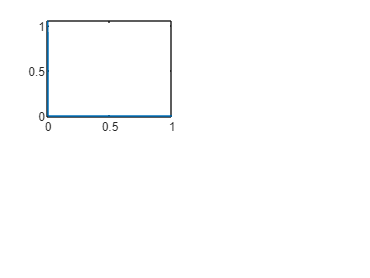

figure(1)
subplot(2,2,1);
plot(t,ans.Vc_out.Data)